clearvars

% Init param
M = zeros(12, 1);
for i = 1:length(M)
    M(i) = 2^i;
end
N_fixed = 2;
[w,z] = GaussHermite_Locations_Weights(N_fixed);
SNR = 1.0;


N = zeros(20, 1);       % No se utiliza
for i = 1:length(N)
    N(i) = i;
end
M_fixed = 1024;         % No se utiliza


rho = 0;
max_rho = 1;
delta = 0.001;
% E0_values = [];  % Pel display
% rho_values = []; % Pel display

maxE0 = -Inf;
best_rho = -1; current_rho = 1;

% Per E0(1) - fors
E0_1 = zeros(length(M), 1);
time_E = zeros(length(M), 1);

for i = 1:length(M)
    [x, q]= PAM_generator(M(i)); % for equiprobable symbols
    tic; % Time starts 
    E0_1(i) = E0(1, N_fixed, q, x, w, z, SNR);
    elapsed_time = toc; % Time ends
    time_E(i) = elapsed_time;
end

% -------------------------------------------------------------
% Per E0(1) - matrius
E0_1_omp = zeros(length(M), 1);
time_E_omp= zeros(length(M), 1);

for i = 1:length(M)
    [x, q]= PAM_generator(M(i)); % for equiprobable symbols
    tic; % Time starts 
    E0_1_omp(i) = E0_omp(1, N_fixed, q, x, w, z, SNR);
    elapsed_time = toc; % Time ends
    time_E_omp(i) = elapsed_time;
end

% -------------------------------------------------------------
% Per F0(1) - fors
F0_1 = zeros(length(M), 1);
time_F = zeros(length(M), 1);

for i = 1:length(M)
    [x, q]= PAM_generator(M(i)); % for equiprobable symbols
    tic; % Time starts 
    F0_1(i) = F0(1, N_fixed, q, x, w, z, SNR);
    elapsed_time = toc; % Time ends
    time_F(i) = elapsed_time;
end


% -------------------------------------------------------------
% Per F0(1) - matrius
F0_1_omp = zeros(length(M), 1);
time_F_omp = zeros(length(M), 1);

for i = 1:length(M)
    [x, q]= PAM_generator(M(i)); % for equiprobable symbols
    tic; % Time starts 
    F0_1_omp(i) = F0_omp(1, N_fixed, q, x, w, z, SNR);
    elapsed_time = toc; % Time ends
    time_F_omp(i) = elapsed_time;
end

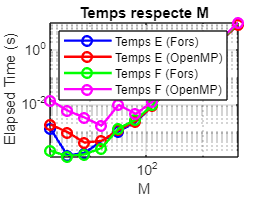

% Display
lim_y = time_E(length(time_E));
if lim_y < time_E_omp(length(time_E_omp))
    lim_y = time_E_omp(length(time_E_omp));
end
if lim_y < time_F(length(time_F))
    lim_y = time_F(length(time_F));
end
if lim_y < time_F_omp(length(time_F_omp))
    lim_y = time_F_omp(length(time_F_omp));
end


% Gràfic
figure;

% Gráfica fors ---- E
loglog(M, time_E, 'o-', 'LineWidth', 1.5, 'Color', 'b', 'DisplayName', 'Temps E (Fors)');

hold on;

% Gráfica matrius ---- E matrix
loglog(M, time_E_omp, 'o-', 'LineWidth', 1.5, 'Color', 'r', 'DisplayName', 'Temps E (OpenMP)');

% Gráfica fors ---- F
loglog(M, time_F, 'o-', 'LineWidth', 1.5, 'Color', 'g', 'DisplayName', 'Temps F (Fors)');

% Gráfica matrius ---- F matrix
loglog(M, time_F_omp, 'o-', 'LineWidth', 1.5, 'Color', 'm', 'DisplayName', 'Temps F (OpenMP)');

grid on;
xlabel('M');
ylabel('Elapsed Time (s)'); 
title('Temps respecte M');
ylim([0 lim_y]);
xlim([0 M(length(M))]);

% Llegenda
legend('show', 'Location', 'northwest');

hold off;

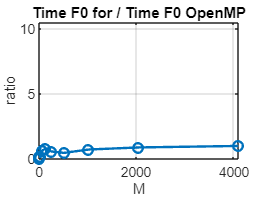

% time F vs time F OpenMP
r = time_F./time_F_omp;
plot(M, r, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('M');
ylabel('ratio'); 
title('Time F0 for / Time F0 OpenMP');
ylim([0 lim_y]);
xlim([0 M(length(M))]);

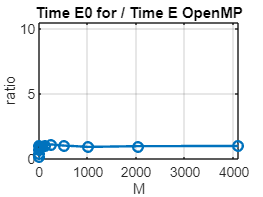



% time E vs time E OpenMP
r = time_E./time_E_omp;
plot(M, r, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('M');
ylabel('ratio'); 
title('Time E0 for / Time E OpenMP');
ylim([0 lim_y]);
xlim([0 M(length(M))]);

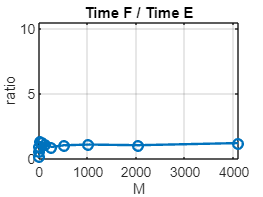



% time E vs time F
r = time_F./time_E;
plot(M, r, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('M');
ylabel('ratio'); 
title('Time F / Time E');
ylim([0 lim_y]);
xlim([0 M(length(M))]);

% Exemple to check
[x, q]= PAM_generator(M(2));
disp("With fors:")

With fors:


[F0_1, F0p_1, F02p_1] = F0(1, 2, q, x, w, z, SNR)

F0_1 =      1.546102970155876e-17


F0p_1 =      1.794583804645213e-17


F02p_1 =     -6.522621905345103e-18


disp("---------------------------------------------")

---------------------------------------------


disp("With OpenMP:")

With OpenMP:


[F0_1_omp, F0p_1_omp, F02p_1_omp] = F0_omp(1, 2, q, x, w, z, SNR)

F0_1_omp =      1.546102970155876e-17


F0p_1_omp =      1.794583804645213e-17


F02p_1_omp =     -6.522621905345103e-18
